% close(1);

% Motor Specs
j_m = 2.367e-6

j_m = 2.3670e-06

K_v = 276.994 % Rpm / V

K_v = 276.9940

K_torque = 60/(2*pi*K_v) % Nm/A

K_torque = 0.0345

% K_torque = 0.036

R = 0.01 % Pinion gear effective radius

R = 0.0100

J = j_m + 1.72e-7 % Motor and pinion moment of inertia

J = 2.5390e-06

m = 2*.343 % Mass of rack and plunger

m = 0.6860

b = 0 % Rotational damping coefficient (includes back emf)

b = 0

c = 286.8 % Linear damping coefficient (includes friction and damping from chest compressions)

c = 286.8000

k = .9*10490 % Spring constant of chest

k = 9441


minimum_gear_ratio = ceil(sqrt((R^2*m)/(3*J)))

minimum_gear_ratio = 4

gear_ratio = 9

gear_ratio = 9

assert(gear_ratio>=minimum_gear_ratio);


T = 10e-3 % Update period of controller

T = 0.0100


s = tf('s');


tau_FOC = 0.00016

tau_FOC = 1.6000e-04


% Full plant, used to size controller gain
plant = (1/(tau_FOC*s + 1))*(R/((J + m*R^2)*s^2 + (b + c*R^2)*s + k*R^2));
[plant_num, plant_denom] = tfdata(plant);
plant_num = plant_num{1};
plant_denom = plant_denom{1};

w_c = 2*pi*13 % rad/s

w_c = 81.6814

phi_m = 75 % deg

phi_m = 75

phi_lag = rad2deg(angle(freqresp(plant, w_c))) - phi_m % deg

phi_lag = -154.4166


% Lag coefficients
K_i = w_c/tand(90 - phi_lag)

K_i = 39.1061


% Lead coefficients
% alpha = (1 + sind(phi_m + phi_lag))/(1 - sind(phi_m + phi_lag))
% tau = 1/(w_c*sqrt(alpha))

% lead_tf = (alpha*tau*s + 1)/(tau*s + 1);
% lag_tf = (s + K_i)/s;
lag_tf = 1 + K_i/s;

K_p = 1/abs(freqresp(plant*lag_tf, w_c))

K_p = 215.5142


controller_tf = K_p*lag_tf;
L = controller_tf*plant;

[num_cont, denom_cont] = tfdata(lag_tf); 
% Generate discrete TF

% lead_discrete = c2d(lead_tf, T, 'matched');
lag_discrete = c2d(lag_tf, T, 'tustin');
leadlag_discrete = lag_discrete;
gain_discrete = abs(freqresp(K_p*lag_tf, .001))/abs(freqresp(leadlag_discrete, .001));

discrete_tf = leadlag_discrete*gain_discrete


discrete_tf =
 
  257.7 z - 173.4
  ---------------
       z - 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


[num_discrete, denom_discrete] = tfdata(discrete_tf);
num_discrete = num_discrete{1}

num_discrete =   257.6539 -173.3746


denom_discrete = denom_discrete{1}

denom_discrete =      1    -1


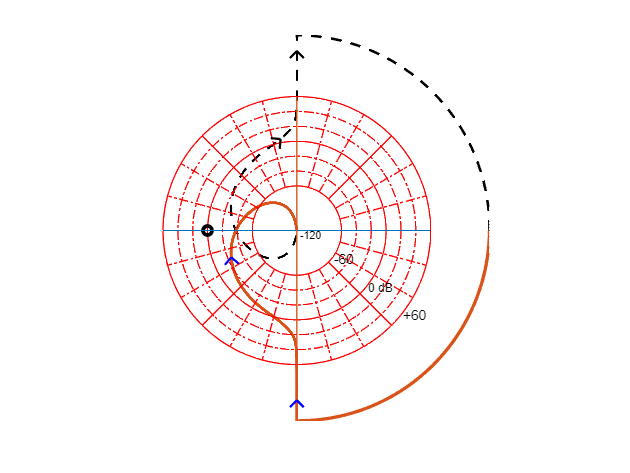

Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   0
=> Number of poles in RHP of closed-loop system:   0
and no closed-loop poles on Im-axis
=> Closed-loop-system is asymptotically stable



figure(1);
nyqlog(L)

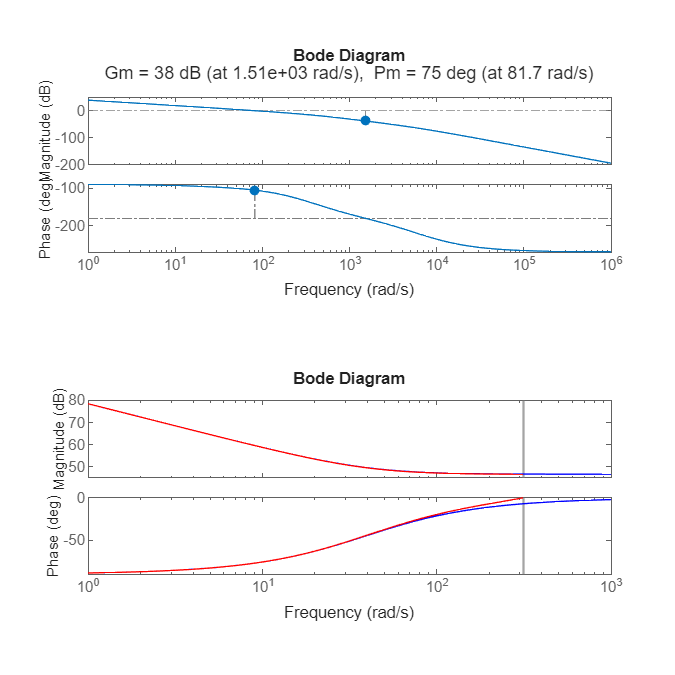


figure(2);
subplot(2, 1, 1)
margin(L)
subplot(2, 1, 2)
bode(controller_tf, 'b')
hold on;
bode(discrete_tf, 'r')
improvePlot


% Verify Sensitivity constraint, S < 2
Sens_max = getPeakGain(1/(1 + L))

Sens_max = 1.1595

assert(Sens_max <= 2)